close all;
mydata = load('RSdata.mat')

mydata = struct with fields:
               rt_tout: [523×1 double]
           rt_Commands: [1×1 struct]
       rt_motor_speeds: [1×1 struct]
             rt_Wrench: [1×1 struct]
         rt_ScopeData3: [1×1 struct]
            rt_v_drone: [1×1 struct]
          rt_phi_drone: [1×1 struct]
         rt_ScopeData2: [1×1 struct]
         rt_ScopeData1: [1×1 struct]
        rt_theta_drone: [1×1 struct]
            rt_u_drone: [1×1 struct]
                  rt_r: [1×1 struct]
                  rt_q: [1×1 struct]
            rt_noisy_q: [1×1 struct]
                  rt_p: [1×1 struct]
      rt_phi_drone_est: [1×1 struct]
    rt_theta_drone_est: [1×1 struct]
                rt_a_y: [1×1 struct]
                rt_a_x: [1×1 struct]
                rt_a_z: [1×1 struct]
                  rt_u: [1×1 struct]
                  rt_v: [1×1 struct]
                  rt_w: [1×1 struct]
        rt_v_drone_est: [1×1 struct]
        rt_u_drone_est: [1×1 struct]
       rt_z_ultrasonic: [1×1 struct]
       

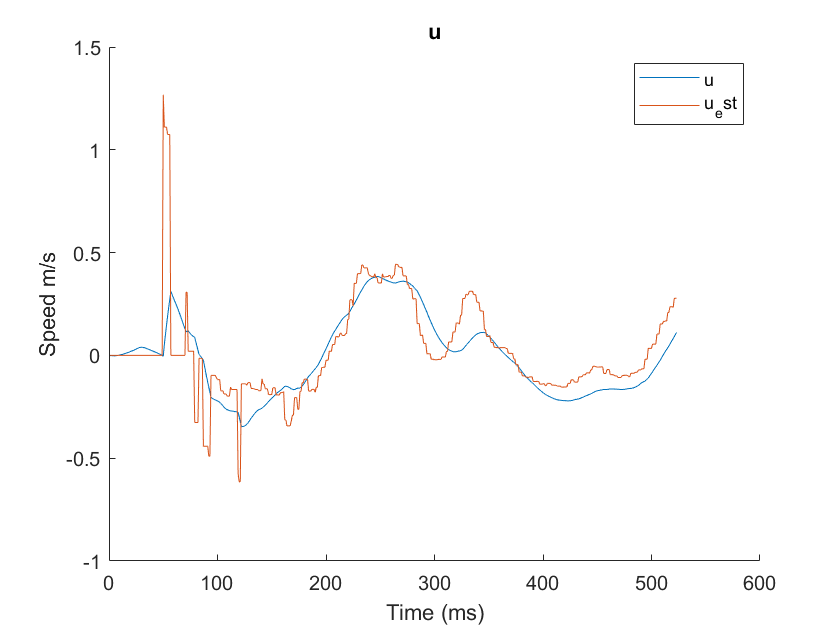



u = mydata.rt_u_drone.signals.values;
u_est = mydata.rt_u_drone_est.signals.values;

figure;
hold on;
plot(u);
plot(u_est)
xlabel("Time (ms)");
ylabel("Speed m/s");
title("u");
legend('u','u_est')
set(gcf,'Visible','on')

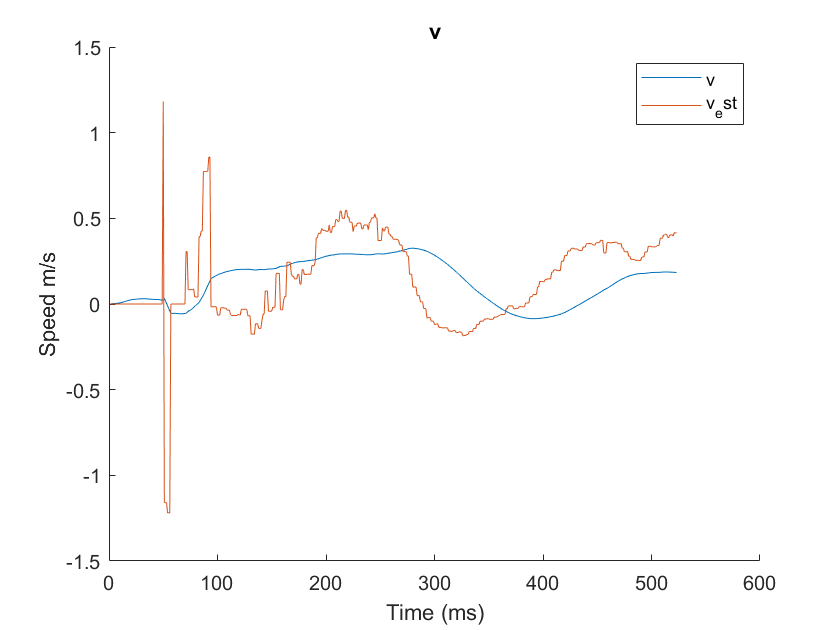



v = mydata.rt_v_drone.signals.values;
v_est = mydata.rt_v_drone_est.signals.values;

figure;
hold on;
plot(v);
plot(v_est);
xlabel("Time (ms)");
ylabel("Speed m/s");
title("v");
legend('v','v_est')
set(gcf,'Visible','on')

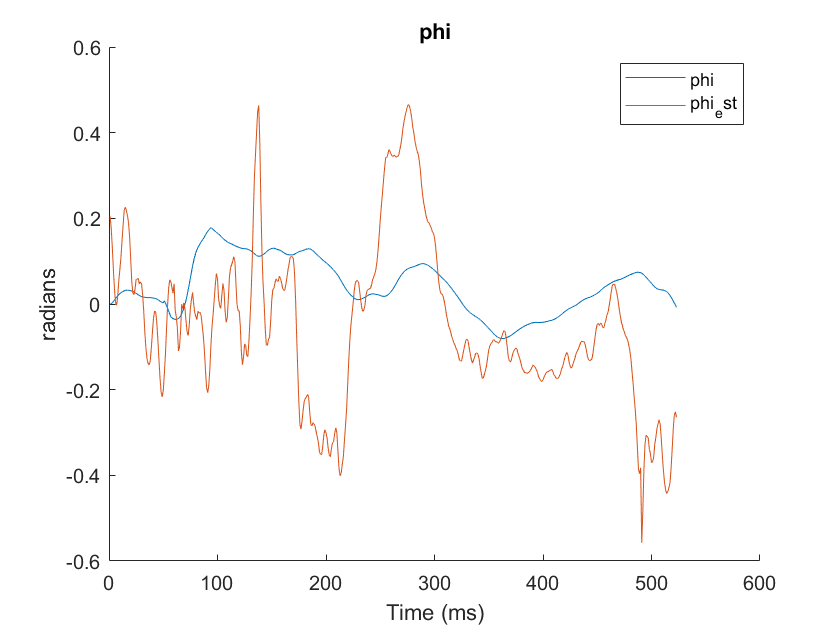



phi = mydata.rt_phi_drone.signals.values;
phi_est = mydata.rt_phi_drone_est.signals.values;
figure;
hold on;
plot(phi);
plot(phi_est)
xlabel("Time (ms)");
ylabel("radians");
title("phi");
legend('phi','phi_est')
set(gcf,'Visible','on')

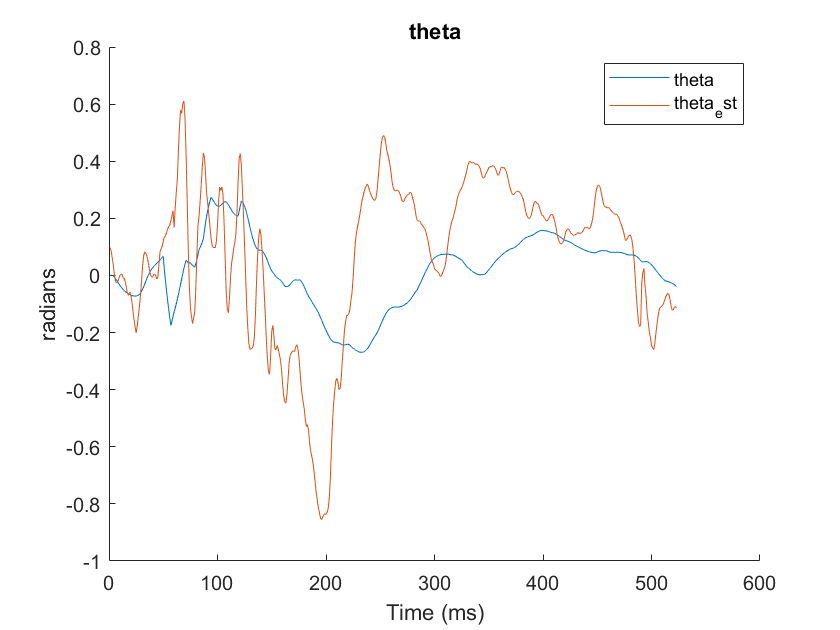



theta = mydata.rt_theta_drone.signals.values;
theta_est = mydata.rt_theta_drone_est.signals.values;
figure;
hold on;
plot(theta);
plot(theta_est)
xlabel("Time (ms)");
ylabel("radians");
title("theta");
legend('theta','theta_est')

set(gcf,'Visible','on')

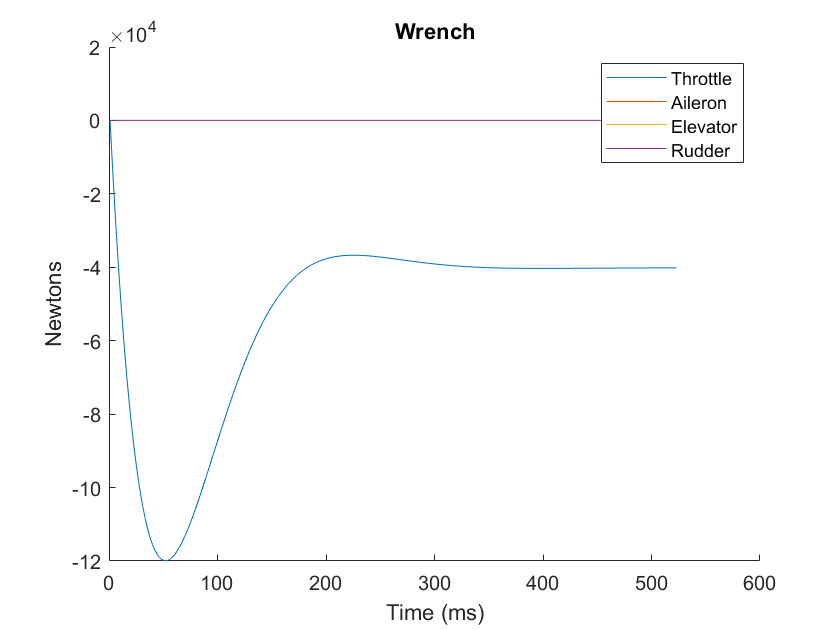



Wrench = mydata.rt_Wrench.signals.values;
figure;
hold on;
plot(Wrench(:,1));
plot(Wrench(:,2));
plot(Wrench(:,3));
plot(Wrench(:,4));
xlabel("Time (ms)");
ylabel("Newtons");
title("Wrench");
legend('Throttle','Aileron','Elevator','Rudder')
set(gcf,'Visible','on')

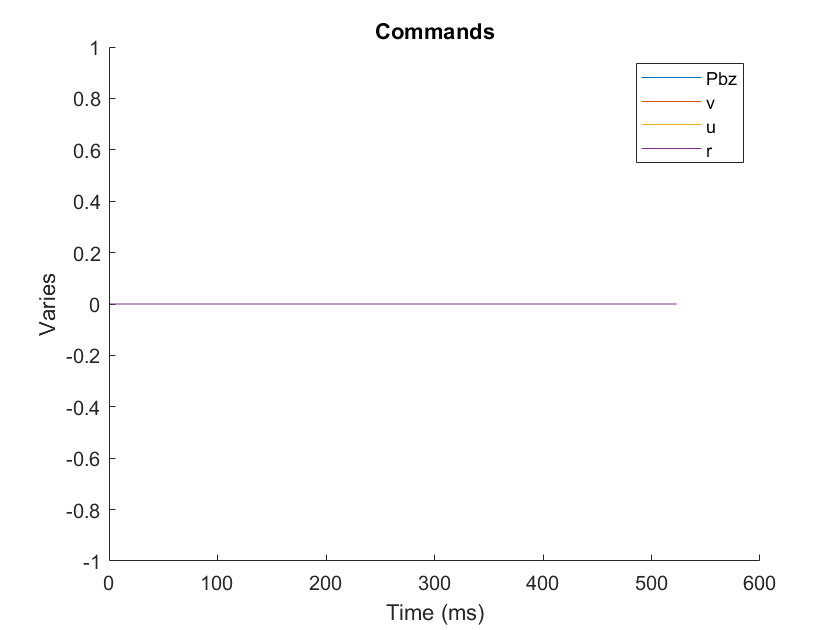


Commands = mydata.rt_Commands.signals.values;
figure;
hold on;
plot(Commands(:,1));
plot(Commands(:,2));
plot(Commands(:,3));
plot(Commands(:,4));
xlabel("Time (ms)");
ylabel("Varies");
title("Commands");
legend('Pbz','v','u','r')
set(gcf,'Visible','on')

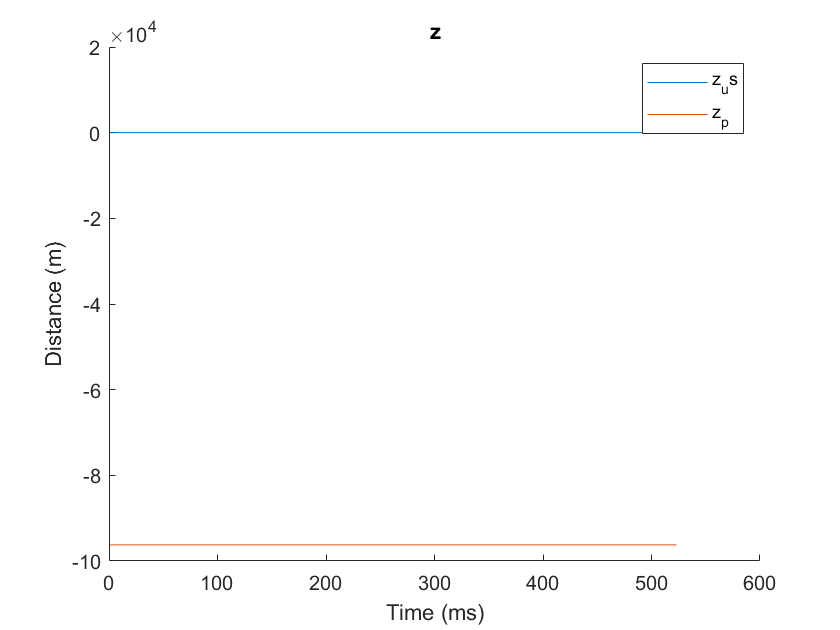


z_us = mydata.rt_z_ultrasonic.signals.values;
z_p = mydata.rt_z_p.signals.values;
figure;
hold on;
plot(z_us);
plot(z_p);
xlabel("Time (ms)");
ylabel("Distance (m)");
title("z");
legend("z_us","z_p")
set(gcf,'Visible','on')

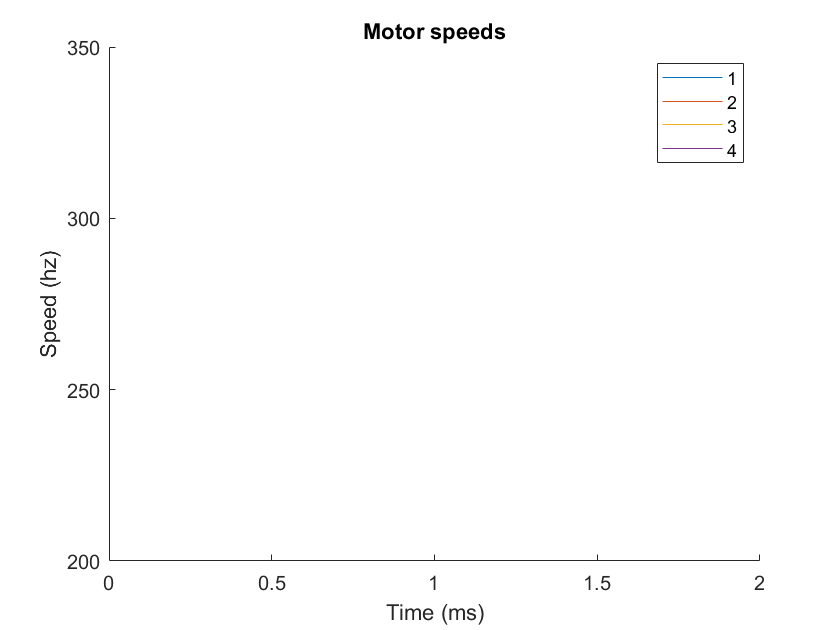


motor_speeds = mydata.rt_motor_speeds_2.signals.values;
figure;
hold on;
plot(motor_speeds(:,1));
plot(motor_speeds(:,2));
plot(motor_speeds(:,3));
plot(motor_speeds(:,4));
xlabel("Time (ms)");
ylabel("Speed (hz)");
title("Motor speeds");
legend('1','2','3','4')
set(gcf,'Visible','on')